%页码：P133
%作者；暴富
%时间：2024-08-1
%%%%%%%%%%%%%完成任务%%%%%%%%%%%%%%%%%%
%验证了位似变化，即特征值乘以c落在Riccati同步区域
%LQR中R必须等于0
%M，N是正定矩阵，其特征值与奇异值相同
%验证了控制器和观测器的稳定区域，以及两者的c不同
%给出了特征值圆的圆心和半径求法
%%c0_SVFB = c0_OBS,r0_SVFB = r0_OBS

clc
clear

%%系统初始化
A = [0,1,0;0,0,1;-0.2,0.2,1.1];
B = [0;0;1];
C = [0,0,1];

G = diag([30,0,0,0,30]);
E = [0 1 1 1 0;...
     1 0 1 1 0;...
     1 1 0 0 1;...
     0 0 1 0 1;...
     0 1 0 1 0];
D = diag(sum(E,2));
L = D -E;
varGamma  = (eye(5)+D+G)\(L+G);

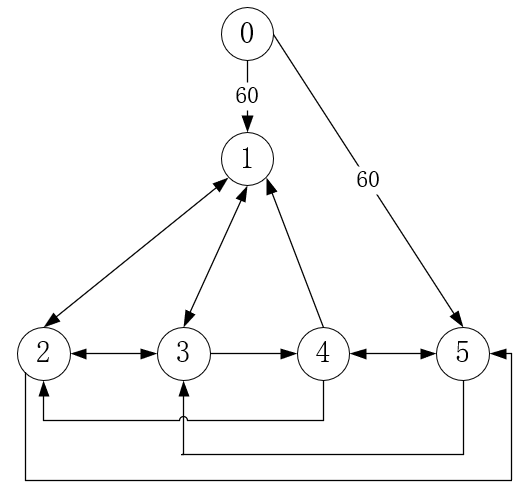

# ---------------------------SVFB---------------------------------

%特征值位置
eig_varGamma = eig(varGamma);
c0_SVFB = (max(real(eig_varGamma))+min(real(eig_varGamma)))/2;
r0_SVFB = max(abs(eig_varGamma - c0_SVFB));


%Riccati设计的稳定区域
Rc = ctrb(A,B);
rank(Rc); %ans = 3结果可控
Q = eye(3); %想要收敛快点就增大对角值
R = 1e-5;%希望控制输入的影响较小
[K,P] = dlqr(A,B,Q,R) ;
%定义矩阵M
M = inv(sqrtm(Q'))*A'*P*B*inv(B'*P*B)*B'*P*A*inv(sqrtm(Q));
r_SVFB = max(svd(M))^(-1/2);


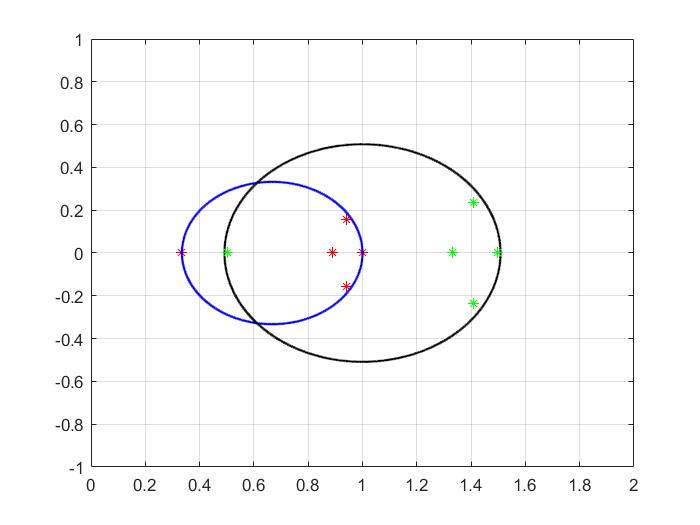

%作图
figure
%特征值分布图
plot(real(eig_varGamma),imag(eig_varGamma),'r*')%表示实部和虚部
hold on
grid on

%绘制特征值分布圆
theta = linspace(0,2*pi,1000);
varGamma_cir = c0_SVFB + r0_SVFB*exp(1j*theta);
plot(real(varGamma_cir),imag(varGamma_cir),'b.','MarkerSize',3)

%Riccati绘制圆，即稳定区域
r_cir = 1 + r_SVFB*exp(1j*theta);
plot(real(r_cir),imag(r_cir),'black.','MarkerSize',3)
axis([0,2,-1,1])

%验证位似变换
r_homothe = eig_varGamma.*(1/c0_SVFB);
plot(real(r_homothe),imag(r_homothe),'g*')


%验证位似变换是否落在稳定区域
c = 1/c0_SVFB;
abs(c*eig_varGamma-1)<r_SVFB;
(r0_SVFB/c0_SVFB)<r_SVFB;

# ---------------------------OBS---------------------------------

%特征值位置
eig_varGamma = eig(varGamma);
c0_OBS = (max(real(eig_varGamma))+min(real(eig_varGamma)))/2;
r0_OBS = max(abs(eig_varGamma - c0_OBS));

%Riccati设计的稳定区域
Ro = obsv(A,C);
rank(Ro); %ans = 3结果可观
Q = eye(3); %想要收敛快点就增大对角值
R = 1e-5;%希望控制输入的影响较小
[F,P] = dlqr(A',C',Q,R);
%定义矩阵N
N = inv(sqrtm(Q'))*A*P*C'*inv(C*P*C')*C*P*A'*inv(sqrtm(Q));
r_OBS = max(svd(N))^(-1/2);

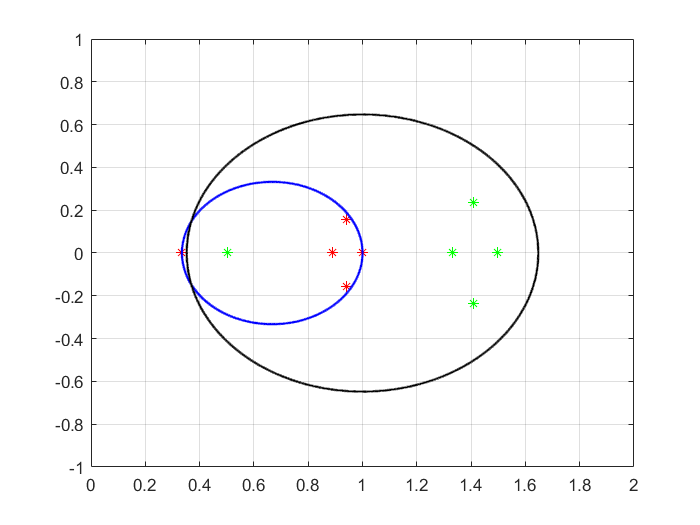

%作图
figure
%特征值分布图
plot(real(eig_varGamma),imag(eig_varGamma),'r*')%表示实部和虚部
hold on
grid on

%绘制特征值分布圆
theta = linspace(0,2*pi,1000);
varGamma_cir = c0_OBS + r0_OBS*exp(1j*theta);
plot(real(varGamma_cir),imag(varGamma_cir),'b.','MarkerSize',3)

%Riccati绘制圆，即稳定区域
r_cir = 1 + r_OBS*exp(1j*theta);
plot(real(r_cir),imag(r_cir),'black.','MarkerSize',3)
axis([0,2,-1,1])

%验证位似变换
r_homothe = eig_varGamma.*(1/c0_SVFB);
plot(real(r_homothe),imag(r_homothe),'g*')


%验证位似变换是否落在稳定区域
c = 1/c0_OBS;
abs(c*eig_varGamma-1)<r_OBS;
(r0_OBS/c0_OBS)<r_OBS;

### ------------验证M和N的特征值与奇异值相同，M，N是正定矩阵-------------------

eig(M)

ans =    3.8700 + 0.0000i
  -0.0000 + 0.0000i
  -0.0000 - 0.0000i


svd(M)

ans =     3.8700
    0.0000
    0.0000
